Steps:

Explain why I haven't found any textbook methods of doing this

- Textbooks talk about the basics and fundmentals and for conciseness don't give every rare example. In the case of enepaq modules it represents a repeated jet of air, flowing out of a hole, of which is a distace away from cyliders. This is a very uncommon method of cooling and is optimized for space efficent use of battery cells, not cooling. Obviously you buy batteries for their battery properies, and textbooks have theory on common applicaitons, merging the two takes some work on the engineering side of things. 

Explain why this is better than cfd/why this is needed before cfd/what are the advantages of cfd

- This is possible to do with cfd, the problem is that in order to get a reasonably accurate cfd model, many parameters have to be somewhat accurately found. 

- Show screenshot of what ansys needs for cfd and ask how you would find parameter values, explain the effects of wrong parameter values. 

- 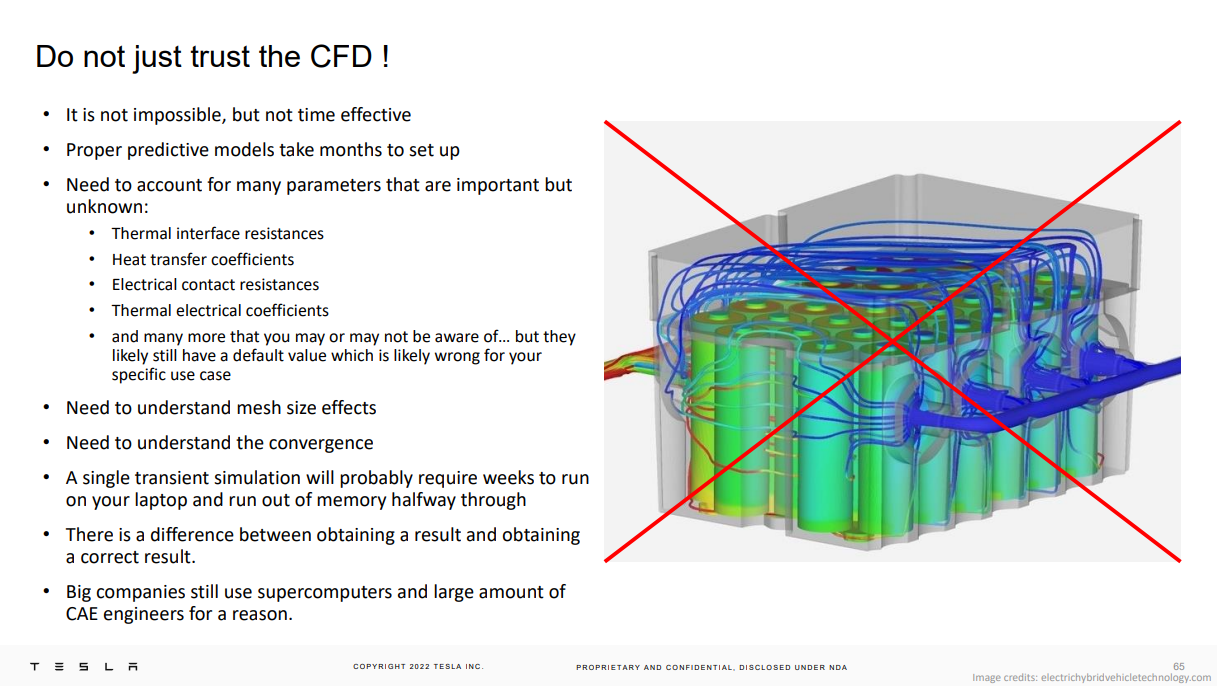note all these things down

Note all needed equations, explain the path of reasoning

Eplain rough experimental setup for determining outputs from possible inputs

Note all assumptions/simplifications/suggestions for additions/including properties

-Missing Insulation layer, decide test needed for that

Give an example of a verified model from the textbook

Use basic equations to guide experiment priorities

- Time of experiment

- Cooling range

-How to go about spotting cells left behind/lesser cooling

To learn

- Repeated non fully developed flow

Tasks

Draft Setup plan

Create list of what equipment is needed

Make machining drawings

To make this script work and be able to predict stuff

- The nusselt number has to be found. This can be found with the below equation. 

I belive that this equation belives that that the Hydralic Diameter D is constant, of which in enepaq modules it is not. Also, the heat transfer coeff H is dependant on many other factors. 

I suppose that If you were able to find a heat transfer coefficent for a one test setup at one speed and were able to find out the reynolds number you could

- Assume the prandl number is roughly constant

- Find C

The enepaq module is a weird shape, so I'm not too sure if they reynolds number could be found. I would also want to pay attention to 

- Entrance/Exit effects

- If the the changes in fluid temperature are significant enough

If I can think of a plan for approximating this in order of effort

- Run tests at differing fan rates, accurately measure intake/exit speed/pressure. If extrapolation is needed use the general trends of increased mass flow vs heat disspation. The mock segment will be reasonable similar, and the properties of aluminum are reasonable close to cells. This value will likely be quite good. 

- Look more into the 7.52 question pasted above. Put a 3d printer heater and temperature sensor in a mock cell. Supply an exact amount of current to the heater cartridge in the cell. Place this cell at the end of the pack and figure out what the effective hydralic diameter is. This represents q in the equation 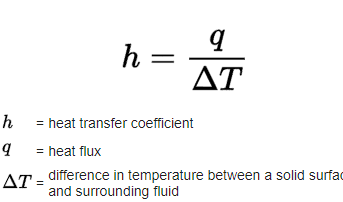 DeltaT is known from the measured cell temp(from a thermocouple). This means we know h(avg) once we note how much area m^2 is exposed to airflow. After this I assume that the reynolds number is averaged through the module(it might not be??). This should allow me to find C. Once I have C I can increase flow, increase the reynolds number and see if it correlates to the experimental results. This could also be done with very finely measuring the temperature of the cell and finding how much heat is dissapated off it. The heater catridge would just allow for steady state. 

DiameterCells = 18.3/1000;%diameter in m
r = DiameterCells/2;
HeightCell = 65/1000;
VolumeCell = HeightCell*r^2*pi;
SurfaceAreaCell = HeightCell*2*pi*r;

ThermalConductivityAlum =	167;% W/m-K
DensityAlum =	2.7*1000;% g/L
SpecificHeatCapacityAlum =	0.896*1000; %J/kg-°C
heatCapCell = DensityAlum * VolumeCell * SpecificHeatCapacityAlum;


The arrays of tube script shows h coefficent values from 15 to 250(0 airflow to 10m/s). This airflow speed is a fairly large guess. I belive that 10m/s could realistically be reached with a 120mm fan. But until I test It would be a good idea to use a value with very little airflow. 20 is likely extremly achiveable(as it represents a very slow airflow)  This can help me dictate how long I expect to test for. 

HTCoeff = 20; %w/(m^2)/k
ThermResis = 1/HTCoeff/SurfaceAreaCell;% Answer in C/w

AmbientTemp = 23;
CellOvenTemp = 60;
%CellOvenTemp = 60:-0.5:23;
deltaT = CellOvenTemp - AmbientTemp;
PowerLoss = deltaT/ThermResis;%Flow out w
%plot(CellOvenTemp,PowerLoss);
dToverDt = PowerLoss/heatCapCell

dToverDt = 0.0669

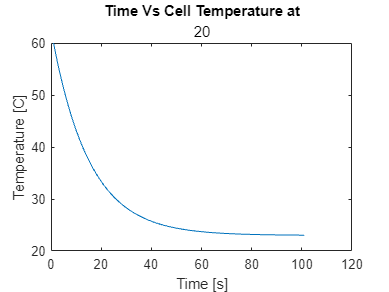


timeExp = 0:1:100;
y = 23+37*exp(-0.0669.*timeExp);
hold on 
plot(y)
title('Time Vs Cell Temperature at')
xlabel('Time [s]');
ylabel('Temperature [C]')
hold off